# Quasi-1D Isentropic nozzle calculator

clear all
gamma_g = 1.33 % bad assumption

gamma_g = 1.3300


T01 = 4196 % degree K

T01 = 4196

P01 = 90000 % Pa

P01 = 90000

M_nozzleexit = 3.4

M_nozzleexit = 3.4000

r_throat = 3.25/1000 %m

r_throat = 0.0033

r_exit = 10.284/1000 %m

r_exit = 0.0103


A_throat = pi*r_throat^2 % m^2

A_throat = 3.3183e-05

A_exit = pi*r_exit^2 % m^2

A_exit = 3.3226e-04



A_As = A_exit/A_throat

A_As = 10.0128

MACH = linspace(3,4,100)

MACH =     3.0000    3.0101    3.0202    3.0303    3.0404    3.0505    3.0606    3.0707    3.0808    3.0909    3.1010    3.1111    3.1212    3.1313    3.1414    3.1515    3.1616    3.1717    3.1818    3.1919    3.2020    3.2121    3.2222    3.2323    3.2424    3.2525    3.2626    3.2727    3.2828    3.2929    3.3030    3.3131    3.3232    3.3333    3.3434    3.3535    3.3636    3.3737    3.3838    3.3939    3.4040    3.4141    3.4242    3.4343    3.4444    3.4545    3.4646    3.4747    3.4848    3.4949


%A_As_list = zeros(1, length(MACH))

A_As_list = (1./MACH).*((2/(gamma_g+1)) .* (1+((gamma_g-1)/2).*MACH.^2)).^((1+gamma_g)/(2*(gamma_g-1)))

A_As_list =     4.8345    4.8872    4.9405    4.9943    5.0488    5.1038    5.1595    5.2158    5.2727    5.3302    5.3883    5.4471    5.5065    5.5666    5.6273    5.6887    5.7508    5.8135    5.8769    5.9410    6.0058    6.0713    6.1374    6.2043    6.2719    6.3403    6.4093    6.4791    6.5497    6.6210    6.6930    6.7659    6.8395    6.9138    6.9890    7.0649    7.1417    7.2193    7.2976    7.3768    7.4569    7.5378    7.6195    7.7020    7.7855    7.8698    7.9550    8.0410    8.1280    8.2158


exitmach = interp1(A_As_list,MACH,A_As)

exitmach = 3.6817


%{
for i=1:length(MACH)
        A_As_list(i) = (1/MACH(i))*((2/(gamma+1)) * (1+((gamma-1)/2)*MACH(i)^2))^((1+gamma)/(2*(gamma-1)))
end
%}




Species = ["CO2"; "CO"; "O"; "O2"; "C"];
MassFraction = [0.0247; 0.621; 0.302; 0.0522; 0.0];
MassFraction(5) = 1 - sum(MassFraction);
sum(MassFraction)

ans = 1

MolecularWeight = [44.01; 28.01; 15.99; 31.999; 12.011];
Gamma = [1.28; 1.4; 1.4; 1.4; 0]

Gamma =     1.2800
    1.4000
    1.4000
    1.4000
         0


Properties = table(Species, MassFraction, MolecularWeight, Gamma)

Properties = 5×4 table
    Species    MassFraction    MolecularWeight    Gamma
    _______    ____________    _______________    _____

     "CO2"        0.0247            44.01         1.28 
     "CO"          0.621            28.01          1.4 
     "O"           0.302            15.99          1.4 
     "O2"         0.0522           31.999          1.4 
     "C"          0.0001           12.011            0 



MolecularWeight_mix = dot(MassFraction,MolecularWeight)

MolecularWeight_mix = 24.9818

R = 8.31446261815324 % J/K/mol

R = 8.3145

R_mix = R/MolecularWeight_mix*1000 % J/kg/K

R_mix = 332.8210

Gamma_mix = dot(Gamma, MassFraction)

Gamma_mix = 1.3969




P_exit = P01/((1+((Gamma_mix-1)/2)*M_nozzleexit^2)^(Gamma_mix/(Gamma_mix-1)))

P_exit = 1.3554e+03

T_exit = T01*((P_exit/P01)^((Gamma_mix-1)/Gamma_mix))

T_exit = 1.2738e+03


a = sqrt(Gamma_mix*R_mix*T_exit)

a = 769.5546

U_exit = M_nozzleexit*a

U_exit = 2.6165e+03

## Stagnation enthalpy

H_g = linspace(2*10^6,25*10^6,10)

H_g = 	1.0e+07 *

    0.2000    0.4556    0.7111    0.9667    1.2222    1.4778    1.7333    1.9889    2.2444    2.5000


U_m = sqrt(2*H_g)

U_m = 	1.0e+03 *

    2.0000    3.0185    3.7712    4.3970    4.9441    5.4365    5.8878    6.3070    6.6999    7.0711


## Stagnation pressure (total pressure at surface

P01_g = linspace(10000,90000,10) %90*1000 %Pa

P01_g = 	1.0e+04 *

    1.0000    1.8889    2.7778    3.6667    4.5556    5.4444    6.3333    7.2222    8.1111    9.0000


gamma_g = Gamma_mix

gamma_g = 1.3969

P_exit_g = 600

P_exit_g = 600

P01_g_P_g = P01_g/P_exit_g

P01_g_P_g =    16.6667   31.4815   46.2963   61.1111   75.9259   90.7407  105.5556  120.3704  135.1852  150.0000


M_g = ((P01_g_P_g.^((gamma_g-1)/gamma_g)-1)./((gamma_g-1)/2)).^0.5 % think this is a poor implimentation, need to check if choked or shock in nozzle etc

M_g =     2.4837    2.8963    3.1533    3.3426    3.4935    3.6194    3.7278    3.8231    3.9084    3.9856


A_As_g = (1./M_g).*((2/(gamma_g+1)) * (1+((gamma_g-1)/2) .* M_g.^2) ).^((1+gamma_g)/(2*(gamma_g-1)))

A_As_g =     2.6049    3.8548    4.9292    5.9006    6.8015    7.6496    8.4561    9.2286    9.9726   10.6921


P02_g = P01_g.*((((gamma_g+1).*M_g.^2)./((gamma_g-1).*M_g.^2+2)).^(gamma_g/(gamma_g-1))).*(((gamma_g+1)./(2*gamma_g.*M_g.^2-(gamma_g-1))).^(1/(gamma_g-1)));
for i = 1:length(P01_g)   
    if A_As_g(i)<A_As
        %then shock in throat
        %assume a normal shock
        
        P02_g(i) = P01_g(i)*(1+((2*gamma_g)/(gamma_g+1))*(M_g(i)^2-1))
    end
    
    
end

P02_g = 	1.0e+04 *

    7.0244    0.6754    0.7952    0.8899    0.9694    1.0385    1.0999    1.1554    1.2062    1.2531


P02_g = 	1.0e+05 *

    0.7024    1.8155    0.0795    0.0890    0.0969    0.1038    0.1100    0.1155    0.1206    0.1253


P02_g = 	1.0e+05 *

    0.7024    1.8155    3.1734    0.0890    0.0969    0.1038    0.1100    0.1155    0.1206    0.1253


P02_g = 	1.0e+05 *

    0.7024    1.8155    3.1734    4.7144    0.0969    0.1038    0.1100    0.1155    0.1206    0.1253


P02_g = 	1.0e+05 *

    0.7024    1.8155    3.1734    4.7144    6.4049    0.1038    0.1100    0.1155    0.1206    0.1253


P02_g = 	1.0e+05 *

    0.7024    1.8155    3.1734    4.7144    6.4049    8.2231    0.1100    0.1155    0.1206    0.1253


P02_g = 	1.0e+06 *

    0.0702    0.1816    0.3173    0.4714    0.6405    0.8223    1.0154    0.0116    0.0121    0.0125


P02_g = 	1.0e+06 *

    0.0702    0.1816    0.3173    0.4714    0.6405    0.8223    1.0154    1.2185    0.0121    0.0125


P02_g = 	1.0e+06 *

    0.0702    0.1816    0.3173    0.4714    0.6405    0.8223    1.0154    1.2185    1.4307    0.0125



gamma_m = Gamma(1)

gamma_m = 1.2800

R_m = R/MolecularWeight(1)*1000

R_m = 188.9221

T_m = 180 % K

T_m = 180

a_m = sqrt(gamma_m*R_m*T_m)

a_m = 208.6328



M_m = U_m./a_m

M_m =     9.5862   14.4678   18.0759   21.0752   23.6978   26.0578   28.2211   30.2300   32.1134   33.8924


Ps_m = zeros(length(M_m),length(P02_g));
for i = 1:length(M_m)
    P02_m = P02_g;
    P02_m_P01_m = ((((gamma_m+1).*M_m(i).^2)./((gamma_m-1).*M_m(i).^2+2)).^(gamma_m/(gamma_m-1))).*(((gamma_m+1)./(2.*gamma_m.*M_m(i).^2-(gamma_m-1))).^(1/(gamma_m-1)));
    P01_m = P02_m./P02_m_P01_m;
    Ps_m(i,:) = P01_m./((1+((gamma_m-1)/2).*M_m(i).^2).^(gamma_m/(gamma_m-1)));
end
Ps_m

Ps_m = 	1.0e+04 *

    0.0632    0.1635    0.2857    0.4244    0.5766    0.7403    0.9141    1.0970    1.2881    0.0113
    0.0278    0.0719    0.1257    0.1868    0.2538    0.3258    0.4023    0.4828    0.5669    0.0050
    0.0178    0.0461    0.0806    0.1197    0.1627    0.2089    0.2579    0.3095    0.3634    0.0032
    0.0131    0.0339    0.0593    0.0881    0.1197    0.1537    0.1898    0.2277    0.2674    0.0023
    0.0104    0.0268    0.0469    0.0697    0.0947    0.1216    0.1501    0.1801    0.2115    0.0019
    0.0086    0.0222    0.0388    0.0577    0.0783    0.1006    0.1242    0.1490    0.1750    0.0015
    0.0073    0.0189    0.0331    0.0492    0.0668    0.0857    0.1059    0.1271    0.1492    0.0013
    0.0064    0.0165    0.0288    0.0428    0.0582    0.0747    0.0923    0.1107    0.1300    0.0011
    0.0057    0.0146    0.0256    0.0380    0.0516    0.0662    0.0818    0.0981    0.1152    0.0010
    0.0051    0.0131    0.0229    0.0341    0.0463    0.0595    0.0734  

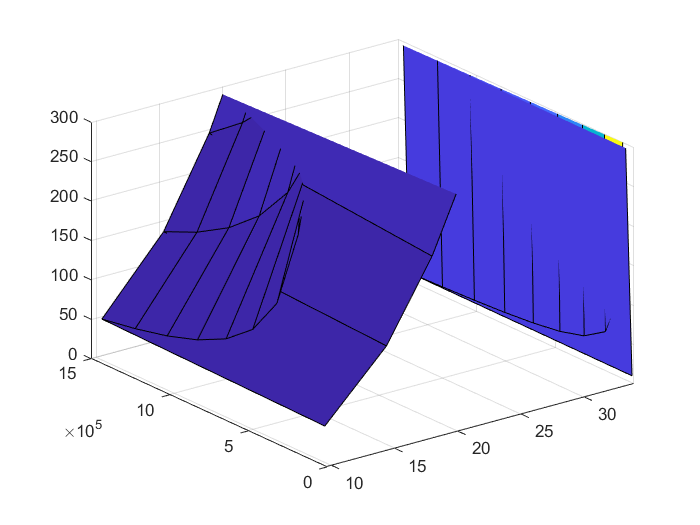

surf(M_m,P02_g,Ps_m)
zlim([0, 300])